## Create training data for initial condition.

Initial condition: $\phi(x) = A \cdot exp \left(-\frac{(x-x_0)^2 + (y-y_0)^2}{\sigma^2} \right)$

here $A$ control the height of the peak value, $(x_0, y_0)$ control the center of the Gaussian, and $\sigma$ control the spread

The following code is how gauss look like

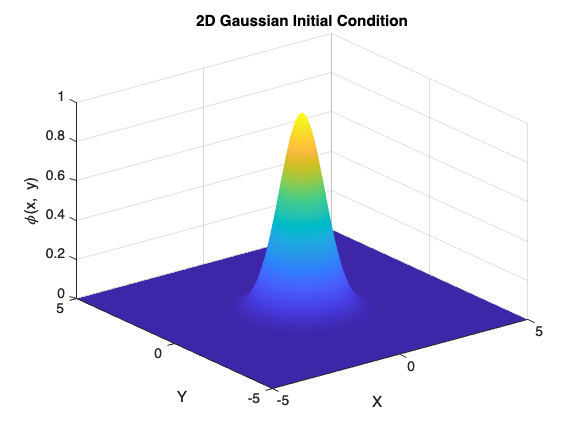

clear;
% Parameters for the Gaussian
A = 1;           % Amplitude
x0 = 0; y0 = 0;  % Center
sigma = 1;       % Spread

% Create a 2D grid
x = linspace(-5, 5, 100);
y = linspace(-5, 5, 100);
[X, Y] = meshgrid(x, y);

% Gaussian function
phi = exp(-X.^2 - Y.^2);

% Plot the initial condition
surf(X, Y, phi);
shading interp;
xlabel('X'); ylabel('Y'); zlabel('\phi(x, y)');
title('2D Gaussian Initial Condition');

## Create Training data for $t>0$ for analytical solution

the analytical solution for wave properaget outward.

we have to change it to Polar coordinate: $u(x,y,t) = \phi(r-ct)$ for $r=\sqrt{(x^2 + y^2)}$

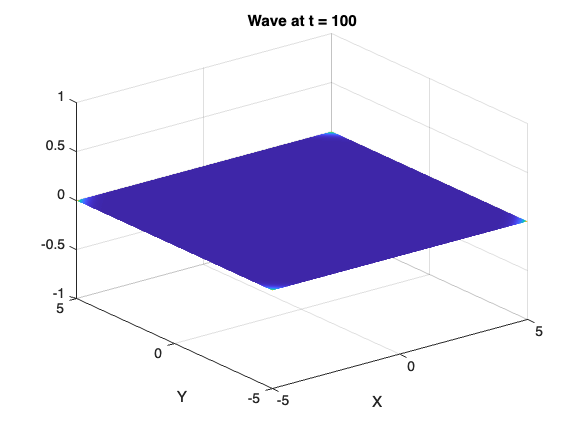

% declare parameters
c = 1; % wave travel speed
t = linspace(0, 10, 100);
R = sqrt(X.^2 + Y.^2);
phi = exp(-((R).^2));

% Analytical solution
u = zeros(size(X, 1), size(X, 2), length(t));
for i = 1:100
    u(:,:,i) = exp(-((R - c * t(i)).^2));
end 

% Animate the analytical solution
for i = 1:100
    surf(X, Y, u(:, :, i));
    shading interp;
    xlabel('X'); ylabel('Y');
    title(['Wave at t = ', num2str((i))]);
    xlim([-5,5]); ylim([-5,5]); zlim([-1,1]);
    pause(0.05);
end

Train the PINN using the provided initial condition.

**Definition of the Neural Network**: So to train the NN is to make the NN predict $u(x,t)$ from any random given $(x,t) \in \Omega$. This will be achieved by training the NN to correctly predict the Initial Condition and Boundary Condition.

**Loss Function**: measuring how well the NN satisify the problem's requirement. In this case, it tells how well the prediction satisfies the PDE, intitial condtion, and boundary condition.

- PDE Residual Loss: ensure $u_{tt} = \Delta u$

- Initial Condtion Loss: ensure $u(x,0) = \phi(x)$

- Boundary Condition Loss: ensure $\nabla u \cdot \widehat{n} \bigg|_{\partial \Omega} = 0$

**Train The network**: We should use a appropriate algorithm to minimize the conbination of all the "loss" above. The idea is similar to Least Mean Square.


$$u_{tt}(x,y,t)=-c^2\phi(x,y)cos(ct))$$


Step 1: Define the training data

we put input and array into colum matricies. travelling from left $\rightarrow$ right, bottom $\rightarrow$ top.

inputs = [];
outputs = [];

% Loop through each time step to populate inputs and outputs
for i = 1:length(t)
    % Create a time vector with the current time step for all spatial points
    t_vector = t(i) * ones(numel(X), 1);  % [N x 1]

    % Flatten (x, y) and concatenate with the time vector
    current_inputs = [X(:), Y(:), t_vector];  % [N x 3]

    % Flatten the corresponding wave data
    current_outputs = u(:, :, i);  % [MxN grid]
    current_outputs = current_outputs(:);    % Flatten to [N x 1]

    % Append to inputs and outputs
    inputs = [inputs; current_inputs];       % Append inputs [N x 3]
    outputs = [outputs; current_outputs];    % Append outputs [N x 1]
end
inputs = inputs';    % [3 x Total_samples]
outputs = outputs';  % [1 x Total_samples]

Step 2: Define a neural net architecture

hiddenLayerSize = [10, 10, 10];  % Number of neurons in the hidden layer
net = fitnet(hiddenLayerSize, 'trainlm');  % 'trainlm' is Levenberg-Marquardt training algorithm

Step 3: Config Training model

net.trainParam.epochs = 50;       % Maximum number of training iterations
net.trainParam.goal = 1e-6;         % Performance goal (mean squared error)
net.trainParam.show = 25;           % Show training progress every 25 epochs

Step 4: Train the neural network

[net, tr] = train(net, inputs, outputs);

Step 5: Evaluate the Neural Network

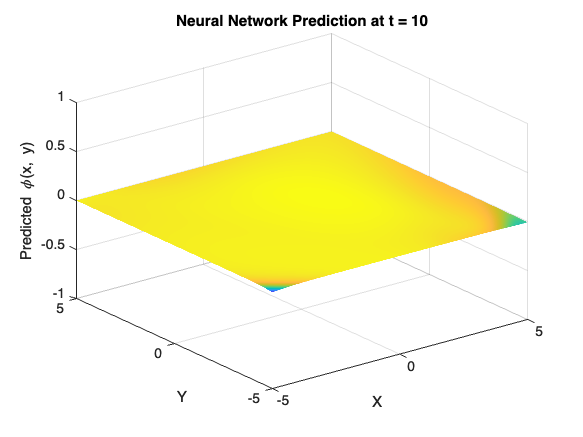

% Step 5: Animate Predictions Over Time
figure;
num_grid_points = numel(X);  % Number of spatial points per time step
for i = 1:length(t)
    % Extract predictions for the current time step
    start_idx = (i - 1) * num_grid_points + 1;
    end_idx = i * num_grid_points;
    predicted_phi_step = net(inputs(:, start_idx:end_idx));  % Predict for current step
    predicted_phi_grid = reshape(predicted_phi_step, size(X));  % Reshape to grid

    % Plot predictions
    surf(X, Y, predicted_phi_grid);
    shading interp;
    xlabel('X'); ylabel('Y'); zlabel('Predicted \phi(x, y)');
    title(['Neural Network Prediction at t = ', num2str(t(i))]);
    xlim([-5, 5]); ylim([-5, 5]); zlim([-1, 1]);  % Adjust limits as needed
    pause(0.05);  % Pause for animation effect
end

% Pre-compute the exact solution for all time steps
exact_solution = zeros(size(X, 1), size(X, 2), length(t));
for i = 1:length(t)
    R = sqrt(X.^2 + Y.^2);  % Radial distance
    exact_solution(:, :, i) = exp(-((R - c * t(i)).^2));  % Exact solution at time t(i)
end

% Extract NN solution for all time steps
predicted_solution = zeros(size(X, 1), size(X, 2), length(t));
for i = 1:length(t)
    % Extract predicted NN solution at each time step
    start_idx = (i - 1) * numel(X) + 1;
    end_idx = i * numel(X);
    predicted_phi_step = net(inputs(:, start_idx:end_idx));  % NN prediction
    predicted_solution(:, :, i) = reshape(predicted_phi_step, size(X));  % Reshape to grid
end

% Compute the error for all time steps
error_all_time = abs(exact_solution - predicted_solution);

% Visualize the error as an animation over the time period
figure;
for i = 1:length(t)
    % Plot the error at the current time step
    surf(X, Y, error_all_time(:, :, i));
    shading interp;
    xlabel('X'); ylabel('Y'); zlabel('Error');
    title(['Error at t = ', num2str(t(i))]);
    colorbar;  % Show color scale for error magnitude
    xlim([-5, 5]); ylim([-5, 5]); zlim([0, max(error_all_time(:))]);  % Adjust limits if needed
    pause(0.05);  % Pause for animation effect
end

Author: Thanh Do.